
CLaVLM = 0.0864;

apexp1 = [-3.099310,-2.064460,-0.908532,0.186504,1.160470,2.194610,3.411570,4.384970,5.480430,6.514580,8.644610,11.322000,12.477300,12.781600,13.511000,14.056300]

apexp1 =    -3.0993   -2.0645   -0.9085    0.1865    1.1605    2.1946    3.4116    4.3850    5.4804    6.5146    8.6446   11.3220   12.4773   12.7816   13.5110   14.0563


clexp1 = [-0.180299,-0.082650,0.011980,0.100509,0.192056,0.274482,0.378259,0.457628,0.555290,0.637716,0.826938,1.055860,1.138310,1.165780,1.211600,1.208680]

clexp1 =    -0.1803   -0.0827    0.0120    0.1005    0.1921    0.2745    0.3783    0.4576    0.5553    0.6377    0.8269    1.0559    1.1383    1.1658    1.2116    1.2087


CLVLM = [-0.1838,-0.0945,0.0053,0.1,0.1842,0.2736,0.3786,0.4624,0.5564,0.6449,0.826,1.0507,1.1464,1.1715,1.2313,1.2759]

CLVLM =    -0.1838   -0.0945    0.0053    0.1000    0.1842    0.2736    0.3786    0.4624    0.5564    0.6449    0.8260    1.0507    1.1464    1.1715    1.2313    1.2759


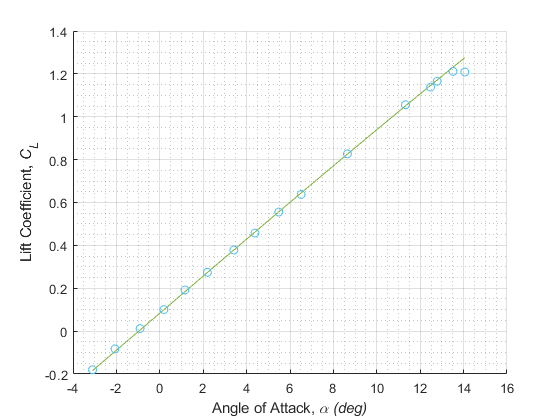


% for i=1:1:length(apexp1)
%     
%     CLVLM(i) = apexp1(i)*CLaVLM + 0.0839;
%     
% end

hold on
plot(apexp1,CLVLM)
scatter(apexp1,clexp1)
hold off
grid on
grid minor
xlabel('Angle of Attack, \it{\alpha} (deg)')
ylabel('Lift Coefficient, \it{C_L}')


PercError = (CLVLM(4:16) - clexp1(4:16))./CLVLM(4:16)

PercError =    -0.0051   -0.0426   -0.0032    0.0009    0.0103    0.0020    0.0111   -0.0011   -0.0049    0.0071    0.0049    0.0160    0.0527



MeanPercErr = mean(abs(PercError))*100

MeanPercErr = 1.2461

Err = CLVLM - clexp1

Err =    -0.0035   -0.0118   -0.0067   -0.0005   -0.0079   -0.0009    0.0003    0.0048    0.0011    0.0072   -0.0009   -0.0052    0.0081    0.0057    0.0197    0.0672


mean_err = mean(Err)

mean_err = 0.0048

mean_abs_err = mean(abs(Err))

mean_abs_err = 0.0095

RMSE = sqrt(mean(Err.^2))

RMSE = 0.0183

std_err = std(Err)

std_err = 0.0183